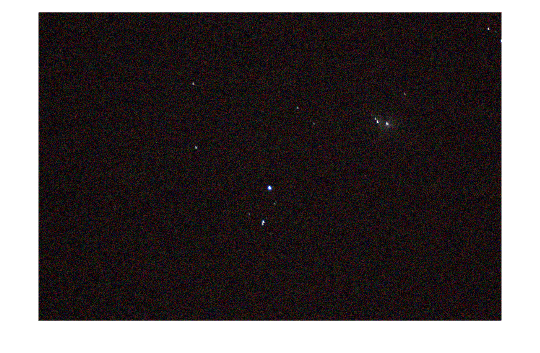

clc ; clear all ; close all ;
img = imread("D:\IMAGES\ORION\pipp_20240331_003120\_MG_0082\_MG_0047.tif"); % Replace with your image file
imshow(img);

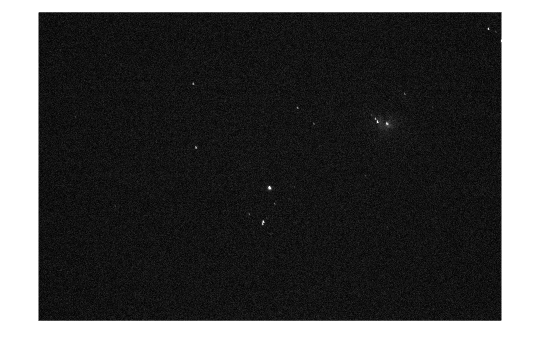

filteredImage = medfilt2(im2gray(img));
imshow(filteredImage);

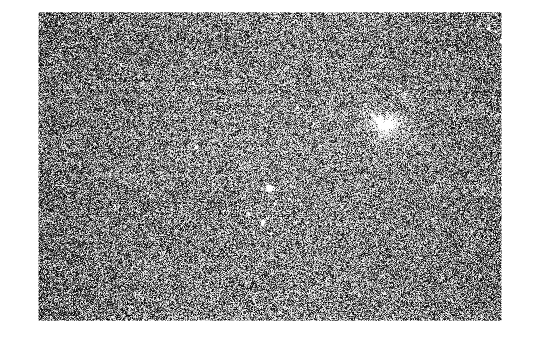

enhancedImg = histeq(filteredImage);
imshow(enhancedImg);

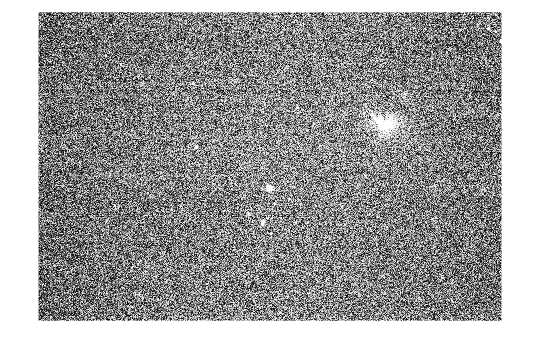

filteredImage1 = medfilt2(enhancedImg,[3 3]);
imshow(filteredImage1);

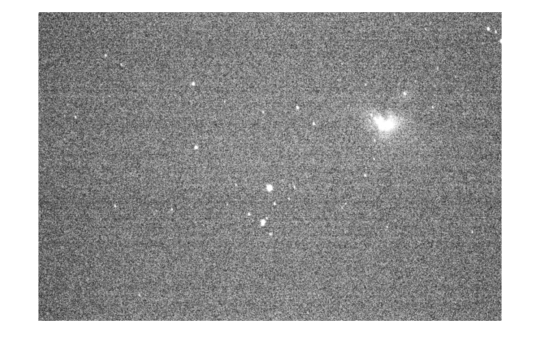

filteredImage2 = imgaussfilt(filteredImage1, 6); 
imshow(filteredImage2);

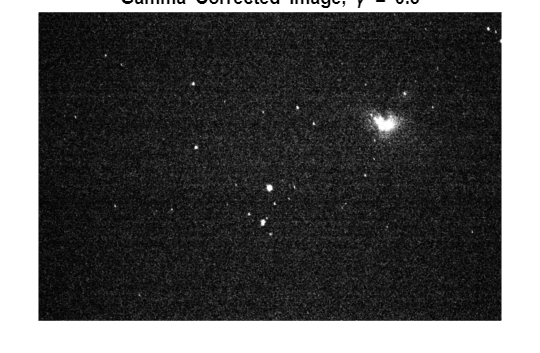

image_double = im2double(filteredImage2);
gamma = 0.3;

% Apply gamma correction to each channel (R, G, B)
corrected1_image = image_double .^ (1/gamma);

% Display the gamma-corrected image
figure;
imshow(corrected1_image);
title(['Gamma Corrected Image, \gamma = ', num2str(gamma)]);

imwrite(corrected1_image, 'orion_image.tif');